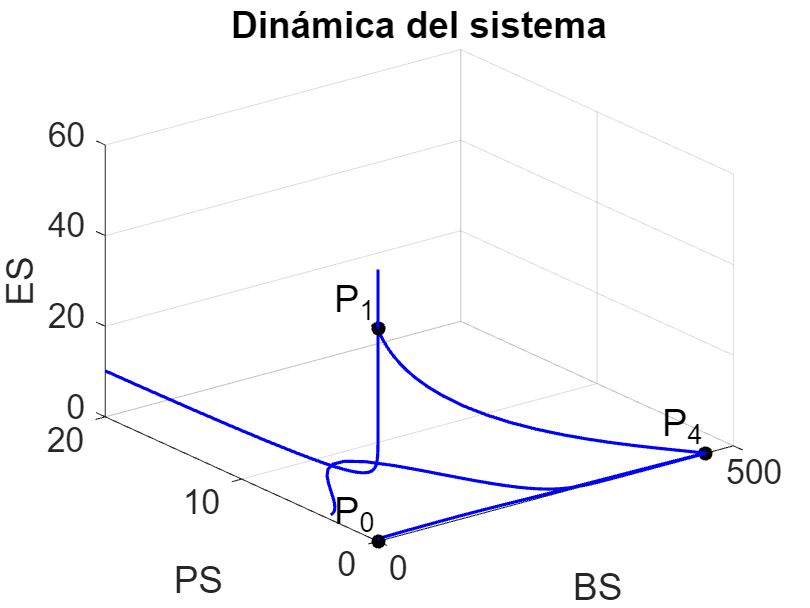

% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Parámetros del sistema
alpha1_val = 0.00137;
beta1_val = 0.07;
gamma1_val = 0.01;
mu1_val = 0.01;
alpha2_val = 0.0011;
beta2_val = 0.29;
gamma2_val = 0.01;
mu2_val = 0.01;
alpha3_val = 0.001;
beta3_val = 0.1;
tau_val = 0.0995;
C_val = 146.9;

region = '4';

if region == '1'
    theta1_val = 0.0435/2;

elseif region == '2'
    theta1_val = (0.0435 + 0.0815)/2;

elseif region == '3'
    theta1_val = (0.0815 + 0.4457)/2;

elseif region == '4'
    theta1_val = 0.5;
end

sigma1 = 1/(2*gamma2_val*mu2_val)*( -(beta2_val*gamma2_val + mu2_val) + sqrt( (beta2_val*gamma2_val-mu2_val)^2 + (4*gamma2_val*mu2_val*alpha2_val*beta3_val)/alpha3_val ) );
sigma2_suma = 1/(2*gamma1_val*mu1_val)*( -((beta1_val-theta1_val)*gamma1_val + mu1_val) + sqrt( ((beta1_val-theta1_val)*gamma1_val-mu1_val)^2 + (4*gamma1_val*mu1_val*alpha1_val*beta3_val)/alpha3_val ) );
sigma2_resta = 1/(2*gamma1_val*mu1_val)*( -((beta1_val-theta1_val)*gamma1_val + mu1_val) - sqrt( ((beta1_val-theta1_val)*gamma1_val-mu1_val)^2 + (4*gamma1_val*mu1_val*alpha1_val*beta3_val)/alpha3_val ) );
M_suma = beta2_val + mu2_val*sigma2_suma;
M_resta = beta2_val + mu2_val*sigma2_resta;
N_suma = gamma2_val*sigma2_suma + 1;
N_resta = gamma2_val*sigma2_resta + 1;
P = alpha2_val*(beta3_val/alpha3_val);

% Definir las ecuaciones del sistema
dx = @(t, x) [
    (alpha1_val * x(1) * (C_val - x(1) - x(2) - x(3))) / (1 + gamma1_val * x(3)) - x(1) * (beta1_val + mu1_val * x(3) - theta1_val);
    (alpha2_val * x(2) * (C_val - x(1) - x(2) - x(3)) * (1 + tau_val * x(1))) / (1 + x(3) * gamma2_val) - x(2) * (beta2_val + mu2_val * x(3));
    alpha3_val * x(3) * (C_val - x(1) - x(2) - x(3)) - beta3_val * x(3)
];


% Definir los puntos críticos
puntos_criticos = [
    0, 0, 0;
    0, 0, C_val - beta3_val / alpha3_val;
    0, C_val - beta2_val / alpha2_val, 0;
    0, C_val - sigma1 - beta3_val/ alpha3_val, sigma1;
    C_val - (beta1_val - theta1_val) / alpha1_val, 0, 0;
    C_val - sigma2_suma - beta3_val/ alpha3_val, 0, sigma2_suma;
    C_val - sigma2_resta - beta3_val/ alpha3_val, 0, sigma2_resta;

    (alpha1_val * beta2_val - alpha2_val * (beta1_val-theta1_val)) / (alpha2_val * (beta1_val-theta1_val) * tau_val), ...
    C_val - (alpha1_val * beta2_val - alpha2_val * (beta1_val-theta1_val)) / (alpha2_val * (beta1_val-theta1_val) * tau_val) - (beta1_val-theta1_val) / alpha1_val, 0;
    
    (alpha3_val*(M_suma*N_suma - P))/(alpha2_val*beta3_val*tau_val), C_val - (alpha3_val*(M_suma*N_suma - P))/(alpha2_val*beta3_val*tau_val) - sigma2_suma - beta3_val/alpha3_val, sigma2_suma;
    (alpha3_val*(M_resta*N_resta - P))/(alpha2_val*beta3_val*tau_val), C_val - (alpha3_val*(M_resta*N_resta - P))/(alpha2_val*beta3_val*tau_val) - sigma2_resta - beta3_val/alpha3_val, sigma2_resta;

    
];

% Filtrar solo los puntos críticos no negativos
puntos_criticos = puntos_criticos(all(puntos_criticos >= 0, 2), :);


% Parámetros de dispersión alrededor de los puntos críticos
num_puntos_cercanos = 1; 
radio = 0.5; 

% Configuración para el gráfico
figure;
hold on;
grid on;
xlabel('BS');
ylabel('PS');
zlabel('ES');
title('Dinámica del sistema');

% Generar y graficar una trayectoria para cada punto crítico
for j = 1:size(puntos_criticos, 1)
    % Contador para asegurar que se generen los puntos requeridos en el primer octante
    num_puntos_validos = 0; 
    while num_puntos_validos < num_puntos_cercanos
        % Generar un punto inicial aleatorio dentro de una esfera de radio especificado
        punto_inicial = puntos_criticos(j, :) + radio * (2 * rand(1, 3) - 1);

        % Comprobar si el punto generado está en el primer octante
        if all(punto_inicial >= 0)
            % Resolver el sistema desde el punto inicial válido cercano al punto crítico
            [t, sol] = ode23s(dx, [0, 1000], punto_inicial);

            % Graficar la trayectoria resultante en azul
            plot3(sol(:,1), sol(:,2), sol(:,3), 'b', 'LineWidth', 1.5);
            
            % Añadir flechas para indicar dirección de la trayectoria (si es necesario)
            num_arrows = 20; % Número de flechas a lo largo de la trayectoria
            indices = round(linspace(1, length(t), num_arrows)); % Índices de puntos donde se colocarán flechas
            for k = 1:length(indices)-1
                % Calcular el vector de dirección
                punto_actual = sol(indices(k), :);
                punto_siguiente = sol(indices(k+1), :);
                direccion = punto_siguiente - punto_actual;

                % Dibujar la flecha
                %quiver3(punto_actual(1), punto_actual(2), punto_actual(3), ...
                %        direccion(1), direccion(2), direccion(3), 'Color', 'k', 'MaxHeadSize', 4);
            end
            
            % Incrementar el contador de puntos válidos
            num_puntos_validos = num_puntos_validos + 1;
        end
    end
end

% Etiquetas para cada región
if strcmp(region, '1')
    labels = {'P_{0}', 'P_{1}', 'P_{4}', 'P_{5}', 'P_{7}', 'P_{8}'};
elseif strcmp(region, '2')
    labels = {'P_{0}', 'P_{1}', 'P_{4}', 'P_{5}', 'P_{8}'};
elseif strcmp(region, '3')
    labels = {'P_{0}', 'P_{1}', 'P_{4}', 'P_{5}'};
elseif strcmp(region, '4')
    labels = {'P_{0}', 'P_{1}', 'P_{4}'};
else
    labels = {}; % Si hay alguna región que no esté definida
end

% Asegurarse de que el número de etiquetas coincida con el número de puntos críticos
num_puntos_criticos = size(puntos_criticos, 1);
if length(labels) > num_puntos_criticos
    labels = labels(1:num_puntos_criticos);  % Recortar etiquetas sobrantes
elseif length(labels) < num_puntos_criticos
    labels = [labels, repmat({'P_{X}'}, 1, num_puntos_criticos - length(labels))];  % Rellenar etiquetas faltantes con genérico
end

% Desplazamiento para las etiquetas (puedes ajustar estos valores)
offset = [0, 0, 0]; % Ajusta el desplazamiento en cada dirección (x, y, z)

% Graficar los puntos críticos y sus etiquetas con desplazamiento
plot3(puntos_criticos(:,1), puntos_criticos(:,2), puntos_criticos(:,3), 'k.', 'MarkerSize', 20);
for j = 1:num_puntos_criticos
    % Calcular la posición de la etiqueta con el desplazamiento
    label_position = puntos_criticos(j, :) + offset;
    text(label_position(1), label_position(2), label_position(3), labels{j}, ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', ...
        'FontSize', 18, 'Color', 'k');
end

p_extra1 = [100, 0,20];
%[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra1);
%plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 

p_extra2 = [10, 4, 0];
[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra2);
plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 

p_extra3 = [15, 0, 28];
%[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra3);
%plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 

p_extra4 = [0,50,10];
[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra4);
plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 

p_extra5 = [0, 0, 60];
[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra5);
plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 

p_extra6 = [110, 0,10];
%[t_p0, sol_p0] = ode23s(dx, [0, 1000], p_extra6);
%plot3(sol_p0(:,1), sol_p0(:,2), sol_p0(:,3), 'b', 'LineWidth', 1.5); 



ax = gca;
ax.FontSize = 16;



xlim([0 500]); %120 - 150 - 300 - 500
ylim([0 20]);  %60 - 50 - 20 - 20 
zlim([0 60]);  %60 - 60 - 60 - 60 



view(3);
hold off;